**Principal Component Analysis**

*Info: eig() is a function that produces a diag. matrix D of eigenvalues and a full matrix V with columns as corresponding eigenvectors -> X*V = V*D*

**Question 1**

*Build the bi-variate time series X = [x1;x2], composed by 100 observation:*

c1 = [2,8];
x1 = randn(1,100);
x2 = polyval(c1,x1)+randn(size(x1));
X = [x1;x2];

*And center each time series with respect to its mean:*

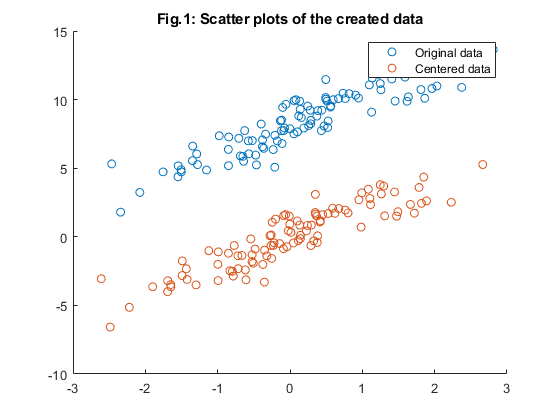

[m,n] = size(X);
mx = mean(X,2);
Xo = X - mx*ones(1,n);

scatter(X(1,:),X(2,:))
hold on
scatter(Xo(1,:),Xo(2,:))
hold off
title("Fig.1: Scatter plots of the created data")
legend('Original data','Centered data')

**Question 2**

*Apply function eig to the covariance matrix Rx (p.4 notes) of Xo so as to achieve its eigenvalue decomposition:*

N = length(Xo);
Rx = Xo*Xo'/(N-1);
[U,D] = eig(Rx);

Orthogonal means that we get the identity when multiplying with transpose

U*U'

ans =     1.0000   -0.0000
   -0.0000    1.0000


D

D =     0.1728         0
         0    6.2487


The columns of U are the eigenvectors corresponding to the diagonal values of D. We see that indeed we only have two eigenvectors and eigenvalues because we only have two dimentional data. We will have n eigenvectors/values for n-Dim data.

**Question 3**

*In the course we have seen that the PCA model can be described as: X = AZ. Generate the matrix of principal components Z and the transfer matrix A, collecting the corresponding eigenvectors, by exploiting the solution for the EVD (eigen value decomp.) model presented in the course, and assuming the covariance matrix of Z to be Rz = (ZZ^T)/(N-1) = I (with I being the identity matrix, and N the number of samples in the multivariate signal Z). *

*Be careful: To solve the indeterminacy on the order of the components, reorganize the eigenvalues in matrix D and the corresponding eigenvectors in matrix U in decreasing order (use functions fliplr and flipud appropriately).*

This is found on p.5, b) section of EVD

Df = rot90(D,2); %same as flipud(fliplr(D))
Uf = fliplr(U);

A = Uf*Df^(1/2);
Z = D^(-1/2)*U'*Xo;

**Question 4**

*Given the expressions for A and Z at the previous question, generate the following figures:*

- *Fig. 2: plot the centered data together with the first and second eigenvectors, using function vectarrow, which you can find in the folder AssignmentPCA.7z (e.g.: vectarrow([0 0],A(:,1)')). Notice the orthogonality of their directions!*

- *Fig. 3: plot the second principal component versus the first, what do you notice?*

- *Fig. 4: reconstruct the original (uncentered) data by using the first principal component only, and make a plot of the original data and their reconstruction.*

*What do you obtain? Why? Try to comment on the result of this projection.*

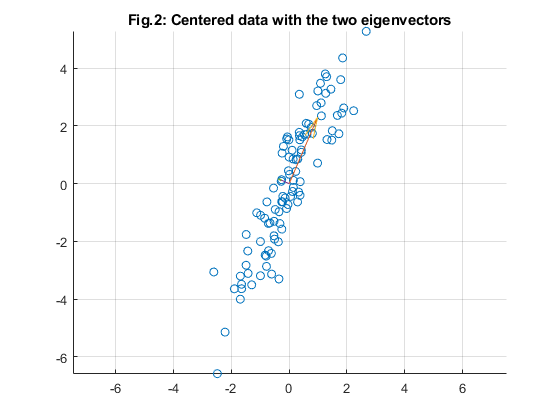

scatter(Xo(1,:),Xo(2,:))
hold on
vectarrow([0 0],A(:,1)')
hold on
vectarrow([0 0],A(:,2)')
hold off
axis equal
title('Fig.2: Centered data with the two eigenvectors')

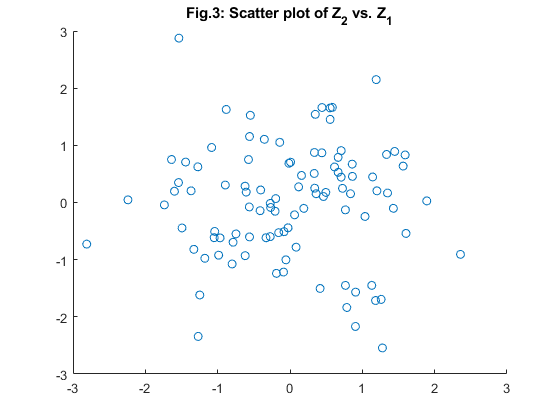

scatter(Z(2,:),Z(1,:))
title('Fig.3: Scatter plot of Z_2 vs. Z_1')

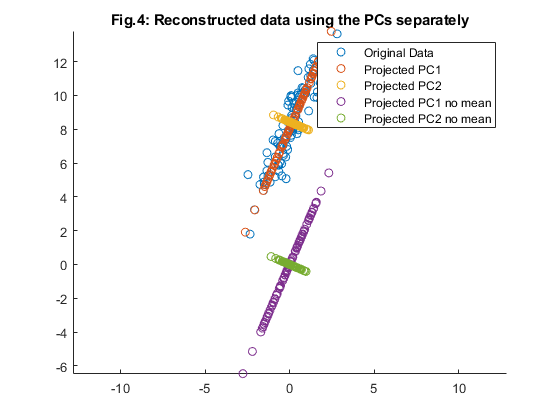


%Projection of the PC1 back onto the original data
%Projections with mean added
x_back1 = A(:,1)*pinv(A(:,1))*Xo + mx;
x_back2 = A(:,2)*pinv(A(:,2))*Xo + mx;
%Projections without mean added
x_back1nm = A(:,1)*pinv(A(:,1))*Xo;
x_back2nm = A(:,2)*pinv(A(:,2))*Xo;

scatter(X(1,:),X(2,:))
hold on
scatter(x_back1(1,:),x_back1(2,:))
hold on
scatter(x_back2(1,:),x_back2(2,:))
hold on
scatter(x_back1nm(1,:),x_back1nm(2,:))
hold on
scatter(x_back2nm(1,:),x_back2nm(2,:))
hold off
axis equal
title('Fig.4: Reconstructed data using the PCs separately')
legend('Original Data','Projected PC1','Projected PC2','Projected PC1 no mean','Projected PC2 no mean')

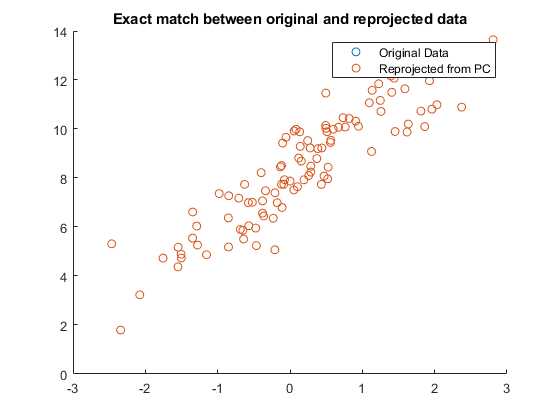

%If I do the reprojection using both PCs, I get back the original data
x_backOri = A(:,1:2)*pinv(A(:,1:2))*Xo + mx;
scatter(X(1,:),X(2,:))
hold on
scatter(x_backOri(1,:),x_backOri(2,:))
hold off
legend('Original Data','Reprojected from PC')
title('Exact match between original and reprojected data')

**Question 5**

*Repeat questions 2 to 4, but this time without centering the data with respect to their mean values. Try to explain the main differences which can be noticed in each figure.*

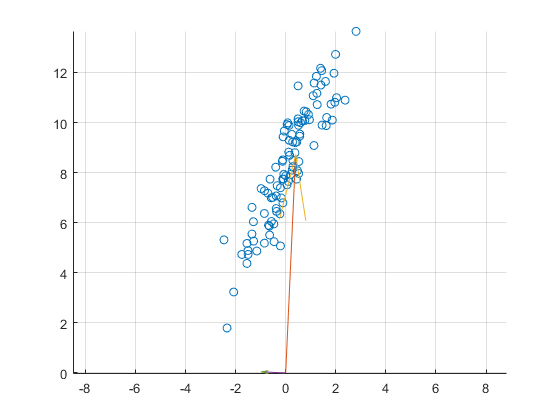

%Q2
N1 = length(X);
Rx1 = X*X'/(N1-1);
[U1,D1] = eig(Rx1);

%Q3
Df1 = rot90(D1,2); %same as flipud(fliplr(D))
Uf1 = fliplr(U1);
A1 = Uf1*Df1^(1/2);
Z1 = D1^(-1/2)*U1'*X;

%Q4
scatter(X(1,:),X(2,:))
hold on
vectarrow([0 0],A1(:,1)')
hold on
vectarrow([0 0],A1(:,2)')
hold off
axis equal

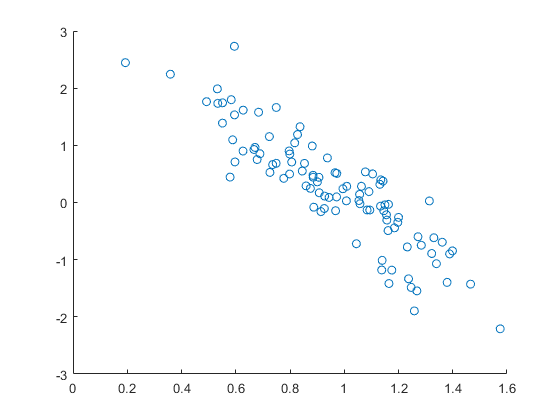

scatter(Z1(2,:),Z1(1,:))

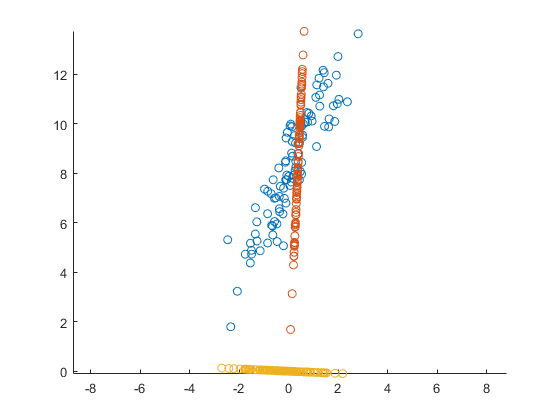

x_back1nm1 = A1(:,1)*pinv(A1(:,1))*X;
x_back2nm1 = A1(:,2)*pinv(A1(:,2))*X;

scatter(X(1,:),X(2,:))
hold on
scatter(x_back1nm1(1,:),x_back1nm1(2,:))
hold on
scatter(x_back2nm1(1,:),x_back2nm1(2,:))
hold off
axis equal

**SEE *****ECG_Question6.mlx *****for the next question about using PCA on ECG data with 12 leads**